## `(1) Preprocessing Part`

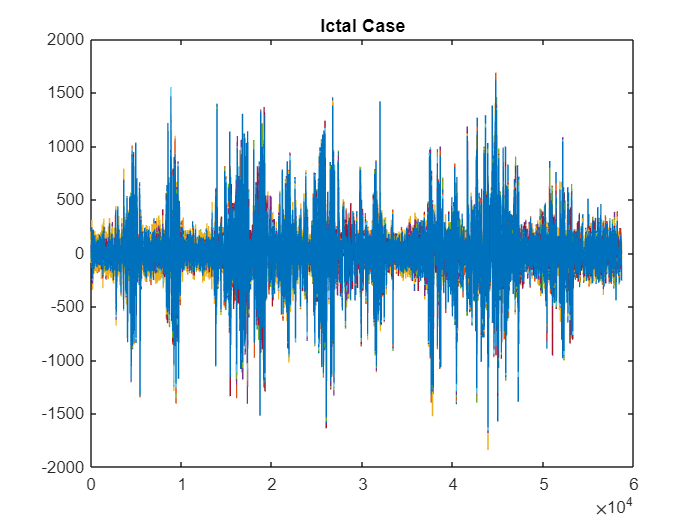

clc 
clear

% Aya
Data = load('chb12_29_data.mat');
fs=256;
ic1=40*fs;
ic2=39*fs;
ic3=37*fs;
ic4=47*fs;
ic5=38*fs;
ic6=28*fs;

ictal1=Data.data(fs*107:(fs*147)-1,: );
ictal2=Data.data(fs*554:(fs*593)-1,: );
ictal3=Data.data(fs*1163:(fs*1200)-1,: );
ictal4=Data.data(fs*1401:(fs*1448)-1,: );
ictal5=Data.data(fs*1884:(fs*1922)-1,: );
ictal6=Data.data(fs*3557:(fs*3585)-1,: );


ictal(1:ic1,:)=ictal1;
ictal(ic1+1:ic1+ic2,:)=ictal2;
ictal(ic1+ic2+1:ic1+ic2+ic3,:)=ictal3;
ictal(ic1+ic2+ic3+1:ic1+ic2+ic3+ic4,:)=ictal4;
ictal(ic1+ic2+ic3+ic4+1:ic1+ic2+ic3+ic4+ic5,:)=ictal5;
ictal(ic1+ic2+ic3+ic4+ic5+1:ic1+ic2+ic3+ic4+ic5+ic6,:)=ictal6;

figure
plot(ictal) % ictal only matrix
title('Ictal Case');

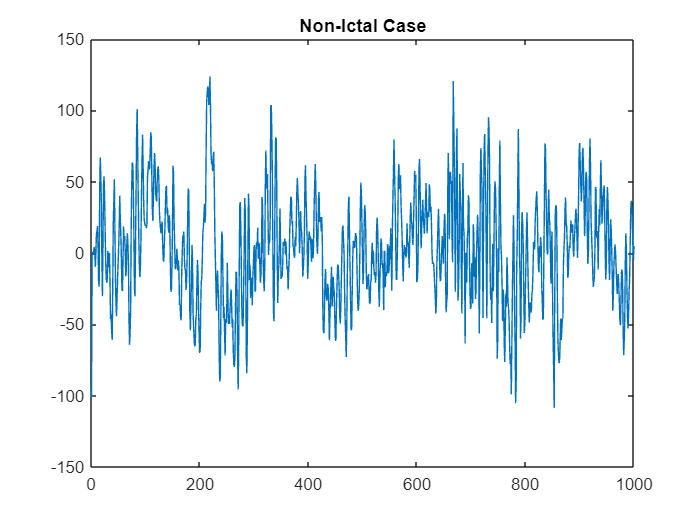


row=load('chb12_32_data.mat');
no_ictal=row.data;
figure
plot(no_ictal(1:1000,2))
title('Non-Ictal Case');

## `(2) Filter Part:`

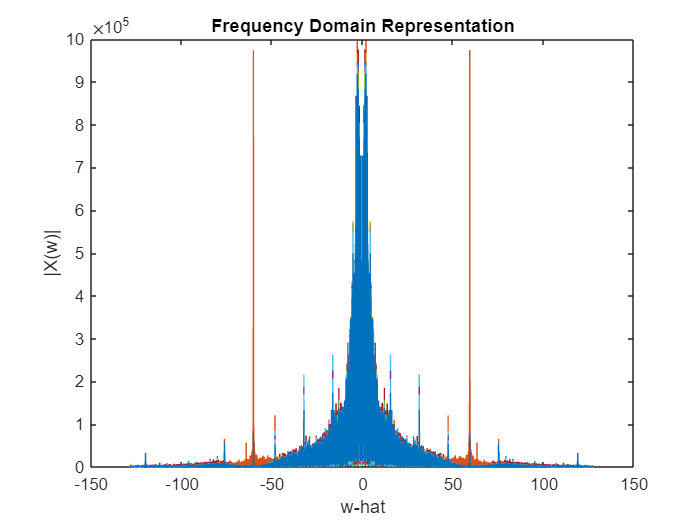

% Shrouk
% Filtering the ictal case
resolution=16384;
N=1:resolution/fs;
ictal_freq = fft(ictal);
sampling=-resolution/2:(resolution/2)-1;
x = linspace(-fs/2,fs/2-1,length(ictal_freq));
figure Name 'Frequency Domain Representation'
%plot(sampling,fftshift( abs(fft(ictal,resolution))))
plot(x, fftshift(abs(ictal_freq)));
title('Frequency Domain Representation')
xlabel('w-hat')
ylabel('|X(w)|')

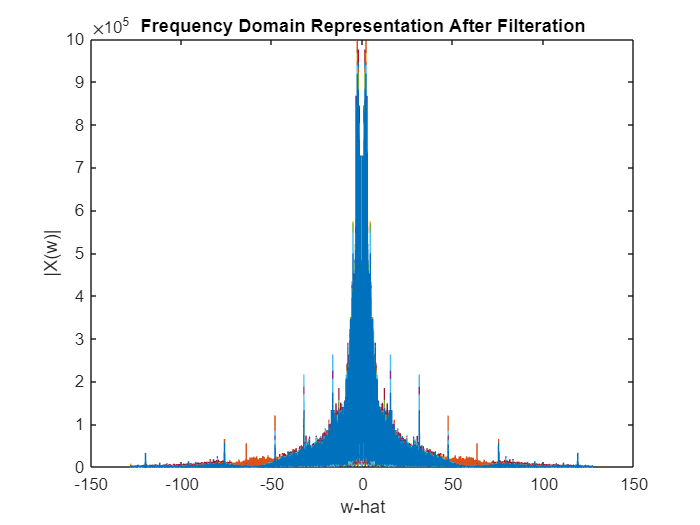

% Filtering the matrix by remvoing 60 Hz
IIR_Filter = designfilt('bandstopiir','FilterOrder',2,'HalfPowerFrequency1',59,'HalfPowerFrequency2',61,'SampleRate',256);
fvtool(IIR_Filter);
freqz(IIR_Filter); % Frequnecy response of the filter
filtered_matrix = filter(IIR_Filter, ictal);
filtered_matrix_freq = fft(filtered_matrix);
figure Name 'Frequency Domain Representation After Filteration'
xx = linspace(-fs/2,fs/2-1,length(filtered_matrix_freq));
plot(xx, fftshift(abs(filtered_matrix_freq)));
title('Frequency Domain Representation After Filteration');
xlabel('w-hat');
ylabel('|X(w)|');

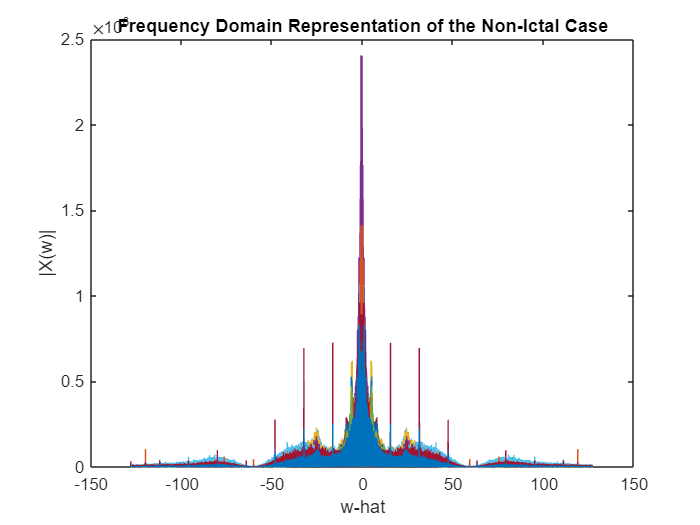

% Filtering the non ictal case

no_ictal_freq = fft(no_ictal);
sampling=-resolution/2:(resolution/2)-1;
x = linspace(-fs/2,fs/2-1,length(no_ictal_freq));
figure Name 'Frequency Domain Representation'
%plot(sampling,fftshift( abs(fft(ictal,resolution))))
plot(x, fftshift(abs(no_ictal_freq)));
title('Frequency Domain Representation of the Non-Ictal Case')
xlabel('w-hat')
ylabel('|X(w)|')

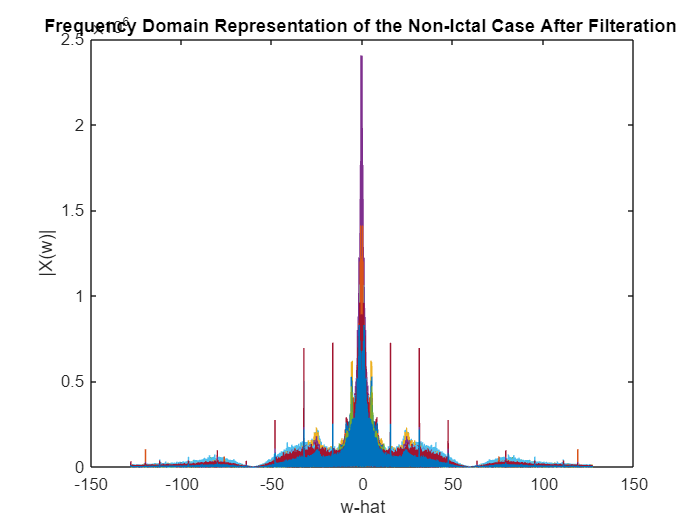

% Filtering the matrix by remvoing 60 Hz
IIR_Filter_no_ictal = designfilt('bandstopiir','FilterOrder',2,'HalfPowerFrequency1',59,'HalfPowerFrequency2',61,'SampleRate',256);
fvtool(IIR_Filter_no_ictal);
freqz(IIR_Filter_no_ictal); % Frequnecy response of the filter
filtered_matrix_no_ictal = filter(IIR_Filter_no_ictal, no_ictal);
filtered_matrix_freq_no_ictal = fft(filtered_matrix_no_ictal);
figure Name 'Frequency Domain Representation After Filteration'
xx = linspace(-fs/2,fs/2-1,length(filtered_matrix_freq_no_ictal));
plot(xx, fftshift(abs(filtered_matrix_freq_no_ictal)));
title('Frequency Domain Representation of the Non-Ictal Case After Filteration ');
xlabel('w-hat');
ylabel('|X(w)|');

%% Averging
 channel1=false;     channel2=false;    channel3=false;       channel4=true;
 channel5=false;     channel6=false;    channel7=false;       channel8=true;
 channel9=false;    channel10=false;   channel11=false;      channel12=false;
channel13=false;    channel14=false;   channel15=false;      channel16=false;
channel17=false;    channel18=false;   channel19=false;      channel20=false;
channel21=false;    channel22=false;   channel23=false;      channel24=false;
channel25=false;    channel26=false;   channel27=false;      channel28=false;
                         channel29=false;

r=[channel1,channel2,channel3,channel4,channel5,channel6,channel7,channel8,... 
   channel9,channel10,channel11,channel12,channel13,channel14,channel15,channel16,...
   channel17,channel18,channel19,channel20,channel21,channel22,channel23,channel24,...
   channel25,channel26,channel27,channel28,channel29];
avg=find(r==1);

collection=filtered_matrix(:,avg);
collection=collection(:,all(~isnan(collection))); 
average = mean(collection,2);

% For the non-ictal
collection_no_ictal=filtered_matrix_no_ictal(:,avg);
collection_no_ictal=collection_no_ictal(:,all(~isnan(collection_no_ictal))); 
average_no_ictal = mean(collection_no_ictal,2);

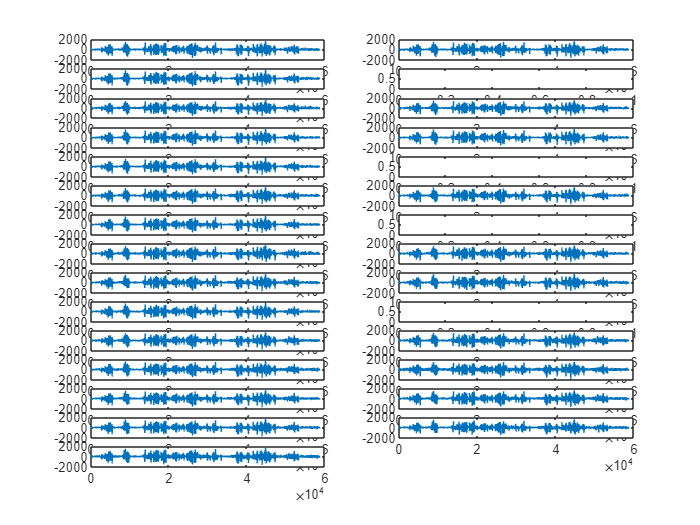

% Vero
figure('Name','The plot of the 29 Ictal channels');
for plotId = 1 : 29
    subplot(15, 2, plotId) ;
    plot(ictal(:,plotId));
end

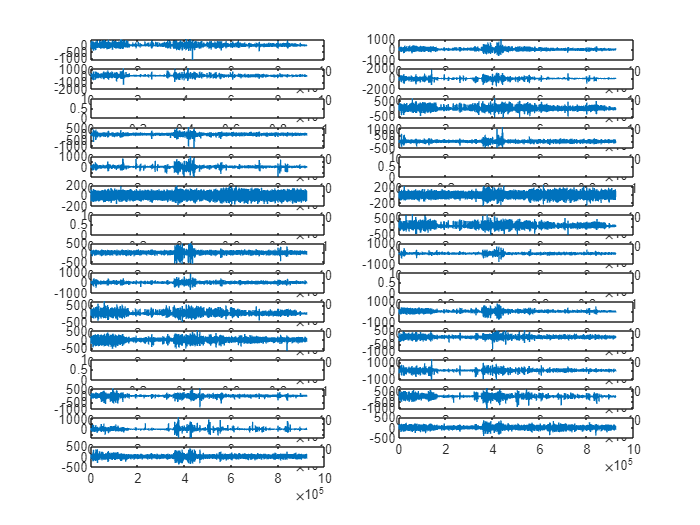


figure('Name','The plot of the 29 No Ictal channels');
for plotId = 1 : 29
    subplot(15, 2, plotId) ;
    plot(no_ictal(:,plotId));
end

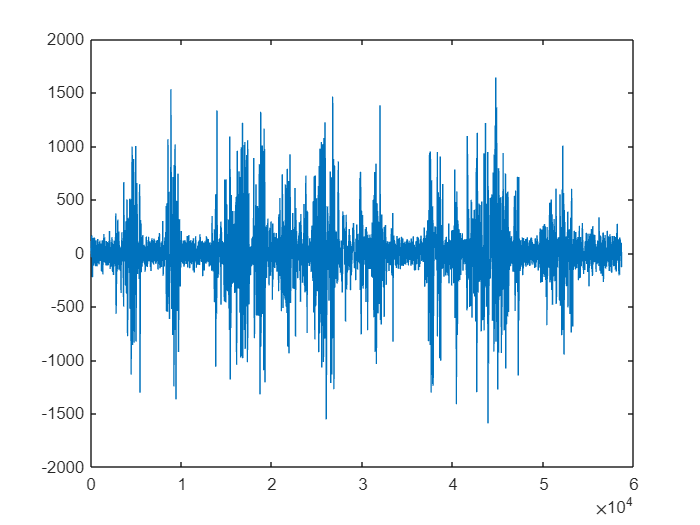


figure('Name','The plot of the average choosed Ictal channels');
plot(average);

%Aya  point 5: Resolution
fs=256;
Time_resolution=32000;


Freq_resolution=16384;
sampling=-Time_resolution/2:(Time_resolution/2)-1;


# `Explain the trade-off between both and the effect of changing each throughout the chosen values.`

The trade-off between time and frequency resolution is called the uncertainty principle of signal analysis, in analogy to Heisenberg's uncertainty principle, which states that **it is not possible to determine the position and velocity of a given particle at the same time, with arbitrary accuracy**.

If the window is too large, it will give a good frequency resolution (the frequency resolution is inversely proportional to the data length), but at the price of a reduced time localization. On the contrary, if the window is too narrow, we will have a good localization in time, but a poor localization in frequency.

%Aya  point 6: Overlapping

OverLap_Ratio=0;

# Show the effect of applying different overlapping ratios:

% Aya point 7: Choosing the window size

window_size=8;
Overlap=ceil((OverLap_Ratio/100)*window_size);



# Investigating the effect of changing it:

% Aya point 8: different window types
Window_Type=blackman(window_size);


%H=wvtool(Window_Type);
% % Rect
% rect_win=rectwin(window_size);
% % Triangular Window256
% = triang(window_size)
%channel
chanel_no=11;

% STFT
%figure Name 'Frequency Domain Representation'
%signal=fftshift( abs(fft((ictal(:,2).*Window_Type),Freq_resolution)))
%plot(sampling,)
signal=average;

time=1:(length(signal)/Time_resolution):length(signal);
res_sig=signal(ceil(time));
final_sig=transpose(res_sig);

% For the non ictal case
signal_no_ictal = average_no_ictal;
timee=1:(length(signal_no_ictal)/Time_resolution):length(signal_no_ictal);
res_sig_no_ictal=signal_no_ictal(ceil(timee));
final_sig_no_ictal=transpose(res_sig_no_ictal);
%stft(ictal, 256, Window = Window_Type,OverlapLength= Overlap, Freq_resolution);

## `Plotting Spectorgram for ictal case:`

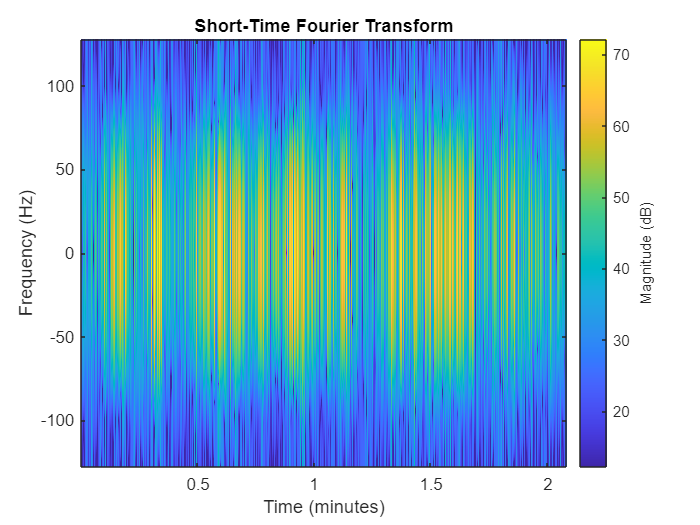

% Using Rectangular Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

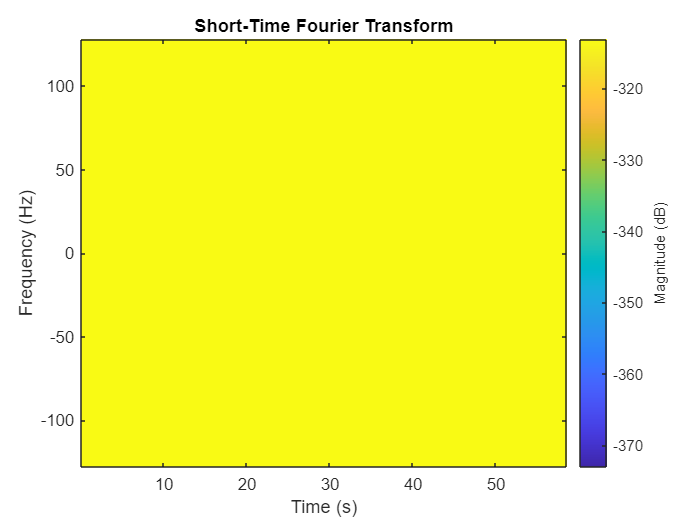

% Using Triangular Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

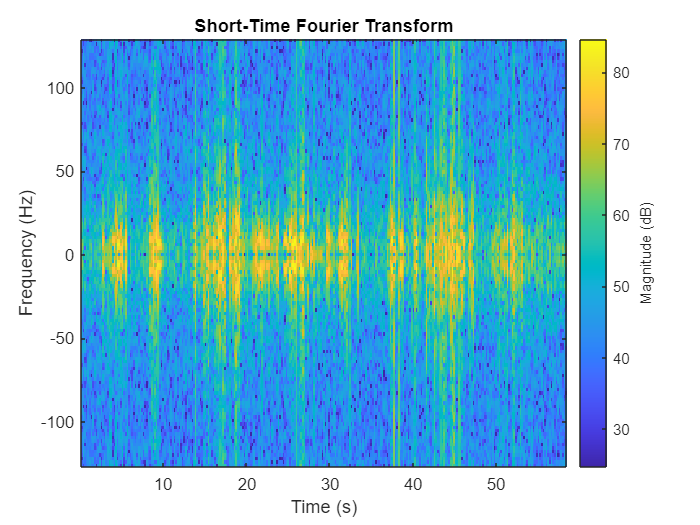

% Using Hanning Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Blackman Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

## `Plotting Spectorgram for non ictal case:`

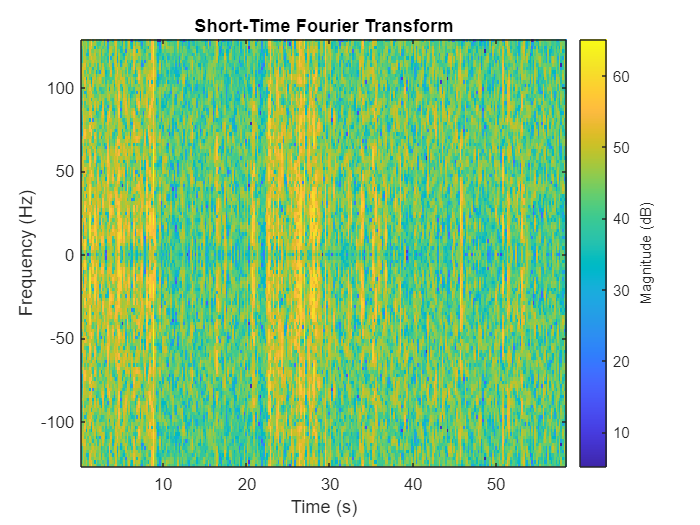

% Using Rectangular Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Triangular Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Hanning Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Blackman Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

## `Plotting Spectorgram when changing overlap ratio to zero for ictal case:`

% Using Rectangular Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Triangular Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Hanning Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Blackman Window and 4,8 channels
stft(final_sig,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

## `Plotting Spectorgram when changing overlap ratio to zero for non ictal case:`


% Using Rectangular Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Triangular Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

% Using Hanning Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

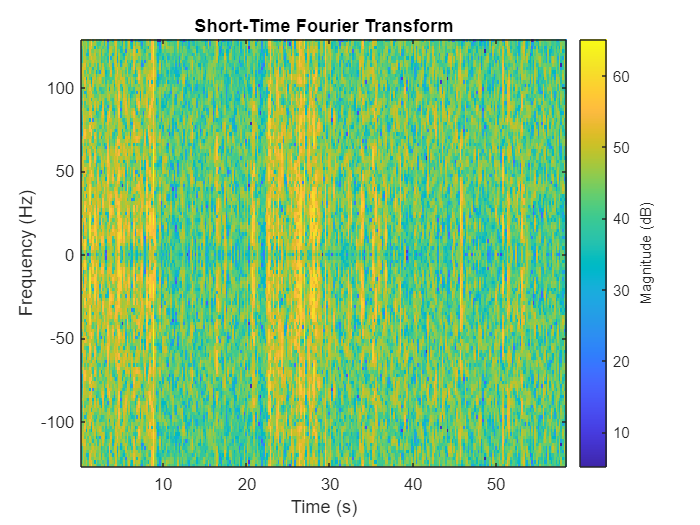

% Using Blackman Window and 4,8 channels
stft(final_sig_no_ictal,fs,Window=Window_Type,OverlapLength=Overlap,FFTLength=Freq_resolution);

# `Comments on the Spectogram Results:`

#### I. When increasing the window size, the time resolution decreases, and hence the leakage decreases.

#### II. The spectrogram when using the Hanning window is better than other windows due to its relatively narrow main lobe width and good attenuation of the first few side lobes, therefore, the contrast between colors of it becomes clear and the sharp edges of frequencies become clear too.

#### III. Changing the overlap length changes the transition of frequencies in the spectrogram.

#### IV. Blackman window has a wide main lobe which is undesirable compared to the Hanning window, but it has more side lobe attenuation which is desirable. 